## Demo of the Fourier uncertainty principle: The trade-off between time resolution and frequency resolution

This demo illustrates the trade-off between the time resolution of a spectral analysis and its ability to resolve activity at different frequencies, known as the Fourer (or Heisenberg) uncertainty principle. In brief, using a longer time segment for estimating a spectrum results in better resolution of the spectrum, compared to using shorter segments. That is, more refined spectral information is available when using a longer segment. But because the spectrum integrates across time points, using longer time segments also means less temporal specificity of the spectrum. 

### Part 1: Representing a narrow-band signal in the DFT amplitude spectrum 

Narrow-band signals are often related to artifacts, or are experimenter-generated brain responses at fixed rate such as the steady-state potential, driven by foxed rate modulation of a stimulus train. Because their exact frequency is known and their quantification often occurs in the frequency domain, they are a great example to illustrate some of the issues that come with the uncertainty principle. 

We start by making a discrete time vector, digitizing the simulated data at 1000 samples per second, i.e. a sample rate of 1000 Hz. 

clear
time = 0.001:0.001:5; % Five seconds of discrete time, sampled at 1000 Hz

now, a Brownian noise (biorealistic) time series not unlike EEG/LFP, representing one trial of neural mass data

temp1 = rand(size(time))-.5; % zero-centered white nois
brownsig = cumsum(temp1);  % Brownian noise is the cumulative sum of white nois

Now, add 10.8 Hz sine wave to the Brownian noise. Note that the 10.8 Hz signal is relatively small and is not easily detected in the time domain data, with the unaided eye. Thus, its waveform shape or time ranges of interest would also be difficult to identify just by looking at the data. Thus, we will conduct DFT later. 

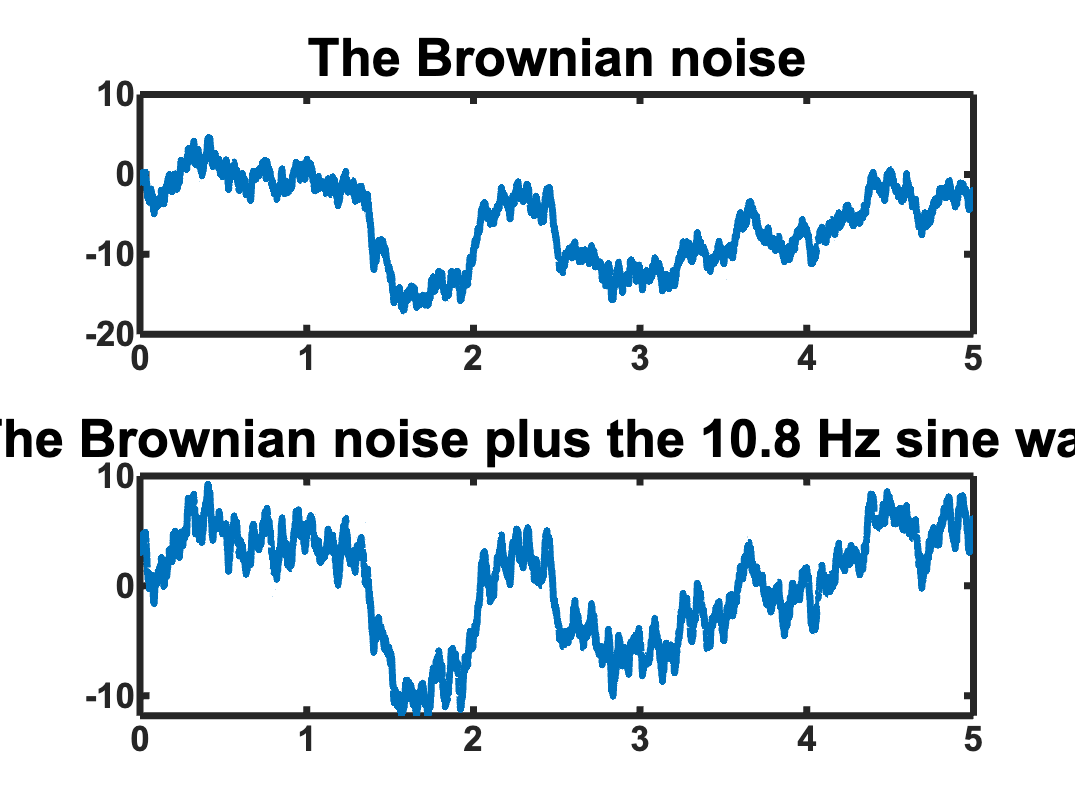

SinWave = sin(2*pi*time*10.8); % a 10.8 Hz sine wave
testsig2  = brownsig-mean(brownsig); % zero-centered Brownian noise
testsig1 = testsig2 + SinWave; % add the sine wave
testsig = detrend(testsig1); % detrend
figure
subplot(2,1,1), plot(time, brownsig), title('The Brownian noise') % the real part
subplot(2,1,2), plot(time, testsig), title('The Brownian noise plus the 10.8 Hz sine wave') 

Next, we compute the Discrete Fourier Transform, resulting in a complex spectrum with real (cosine-base) and imaginary (sine-base) components, then we plot the amplitude spectrum. Note the pronounced 1/f shape of the spectrum, with lower frequencies showing higher amplitude. 

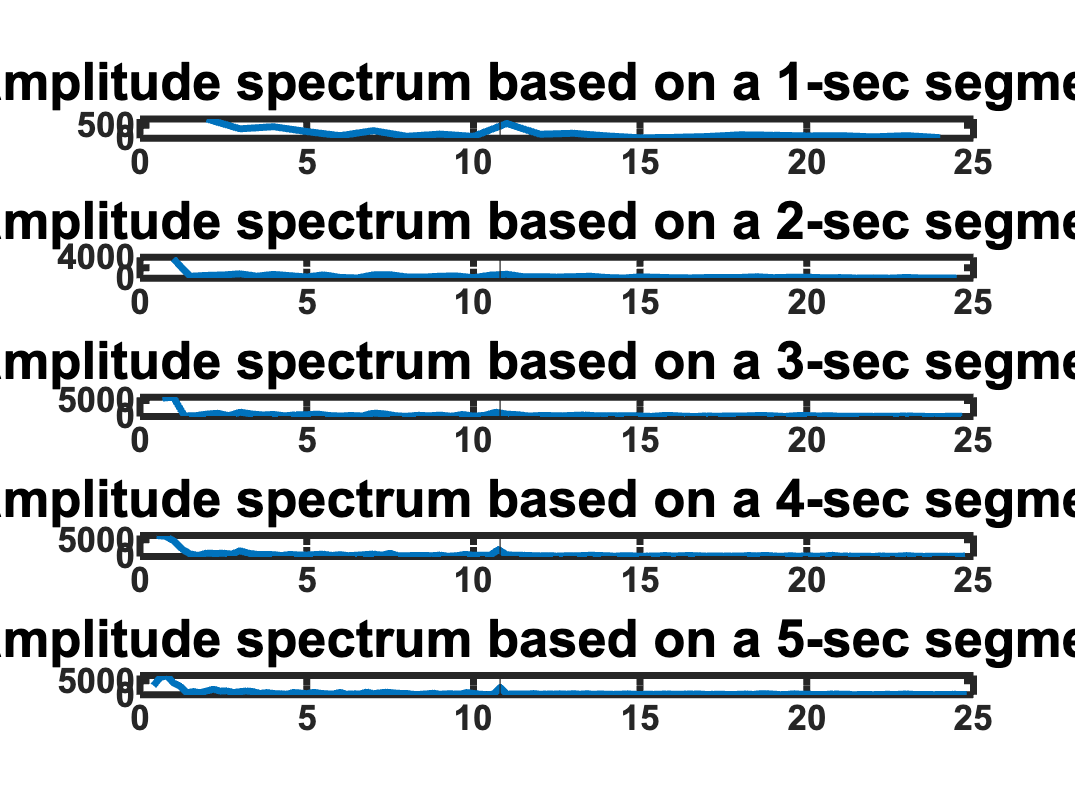

figure
for index = 1:5
    segment = 1:1000*index; % look at increasing segments
    complexspectrum = fft(testsig(segment));
    faxis = 0:1000/length(segment):500; % the frequancy axis always ranges from 0 to 500, but steps get smaller as length increases
    amplitudespec = complexspectrum./length(segment); % normalized amplitude spectrum
    subplot(5,1,index), b1 = plot(faxis(3:25*index), abs(complexspectrum(3:25*index))); title(['amplitude spectrum based on a ' num2str(index) '-sec segment']) % the absolute value (amplitude)
    xline(10.8)
end

Plot the spectra again, but zoomed in, for better visualization of the 10.8 Hz signal. 

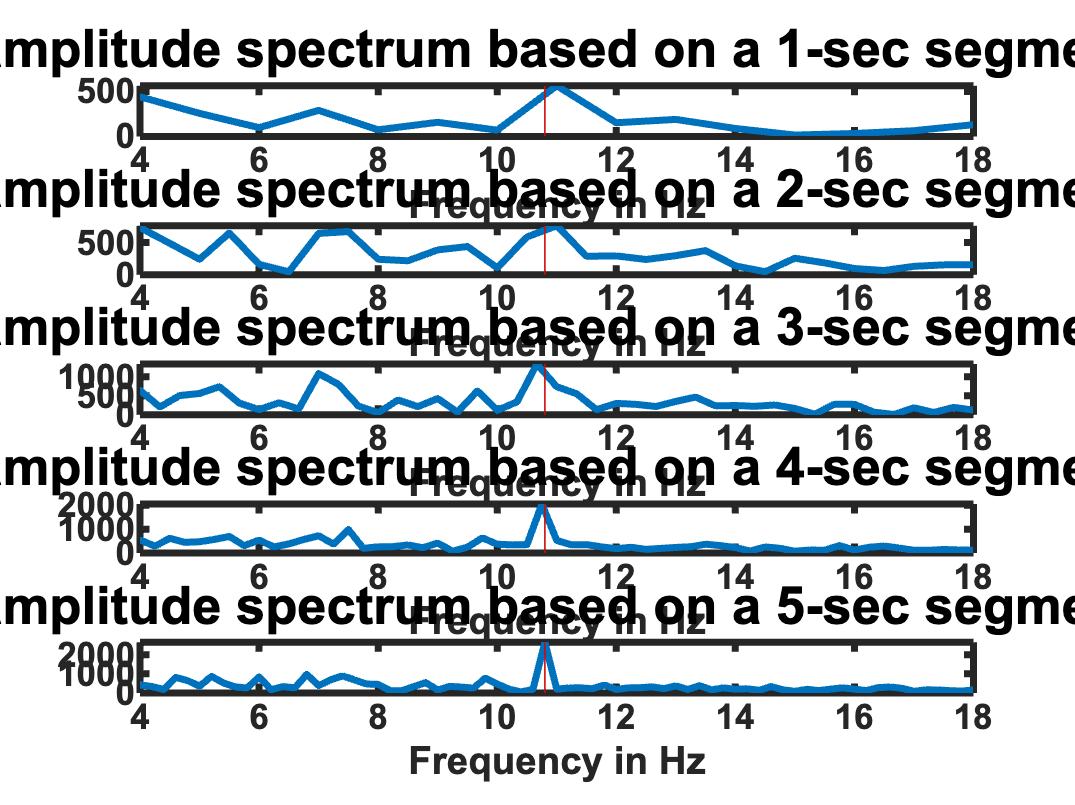

figure
for index = 1:5
    segment = 1:1000*index; % look at increasing segments
    complexspectrum = fft(testsig(segment));
    faxis = 0:1000/length(segment):500; % the frequancy axis always ranges from 0 to 500, but steps get smaller as length increases
    amplitudespec = complexspectrum./length(segment); % normalized amplitude spectrum
    subplot(5,1,index), b1 = plot(faxis(3:25*index), abs(complexspectrum(3:25*index))); title(['amplitude spectrum based on a ' num2str(index) '-sec segment']) % the absolute value (amplitude)
    xline(10.8)
    xlabel('Frequency in Hz') 
    xlim([4 18])
    xline(10.8, 'r')
end

Note that with increasing duration of the segment entered into DFT, the spectrum becomes more fine-grained. It is also clear from the above that the 10.8 Hz narrow band signal (vertical red line) is best captured by the 5 second time window , where the frequency resolution (the distance of the bins on the x-axis) is 1/5 = 0.2 Hz. With the other segment lengths, there is no x-tick that corresponds to 10.8 Hz. For example, with a 3 second window, the resolution is 1/3 = 0.33 Hz, and thus the spectrum will have bins at the following frequencies, none of which corresponds to 10.8 Hz:

frequencies = 0:1/3:30;
disp('frequencies (Hz) available in the spectrum based on a 3-second data segment:')

frequencies (Hz) available in the spectrum based on a 3-second data segment:


disp(frequencies')

         0
    0.3333
    0.6667
    1.0000
    1.3333
    1.6667
    2.0000
    2.3333
    2.6667
    3.0000
    3.3333
    3.6667
    4.0000
    4.3333
    4.6667
    5.0000
    5.3333
    5.6667
    6.0000
    6.3333
    6.6667
    7.0000
    7.3333
    7.6667
    8.0000
    8.3333
    8.6667
    9.0000
    9.3333
    9.6667
   10.0000
   10.3333
   10.6667
   11.0000
   11.3333
   11.6667
   12.0000
   12.3333
   12.6667
   13.0000
   13.3333
   13.6667
   14.0000
   14.3333
   14.6667
   15.0000
   15.3333
   15.6667
   16.0000
   16.3333
   16.6667
   17.0000
   17.3333
   17.6667
   18.0000
   18.3333
   18.6667
   19.0000
   19.3333
   19.6667
   20.0000
   20.3333
   20.6667
   21.0000
   21.3333
   21.6667
   22.0000
   22.3333
   22.6667
   23.0000
   23.3333
   23.6667
   24.0000
   24.3333
   24.6667
   25.0000
   25.3333
   25.6667
   26.0000
   26.3333
   26.6667
   27.0000
   27.3333
   27.6667
   28.0000
   28.3333
   28.6667
   29.0000
   29.3333
   29.6667
   30.0000

The absence of a bin at a given frequency will cause any narrow-band signal at that frequency to be represented at multiple other bins, typically the bins closest to the actual frequency. This is often called *leaking*, where spectral energy is showing up at frequencies other than the actual frequency, because of insufficient resolution of the spectrum. 

Once a signal is not well represented in a DFT amplitude spectrum, it is difficult to recover. One intution a researcher may have is that averaging several trial will help to improve the measurement, despite suboptimal choice of segment duration. This field tests this assumption using our example. Let's make 50 segments and average the spectra based on 1-sec segments. To make things more interesting, let's use a 10.5 Hz oscillation, in between the 10 and 11 Hz bins which are represented in a 1-sec spectrum. 

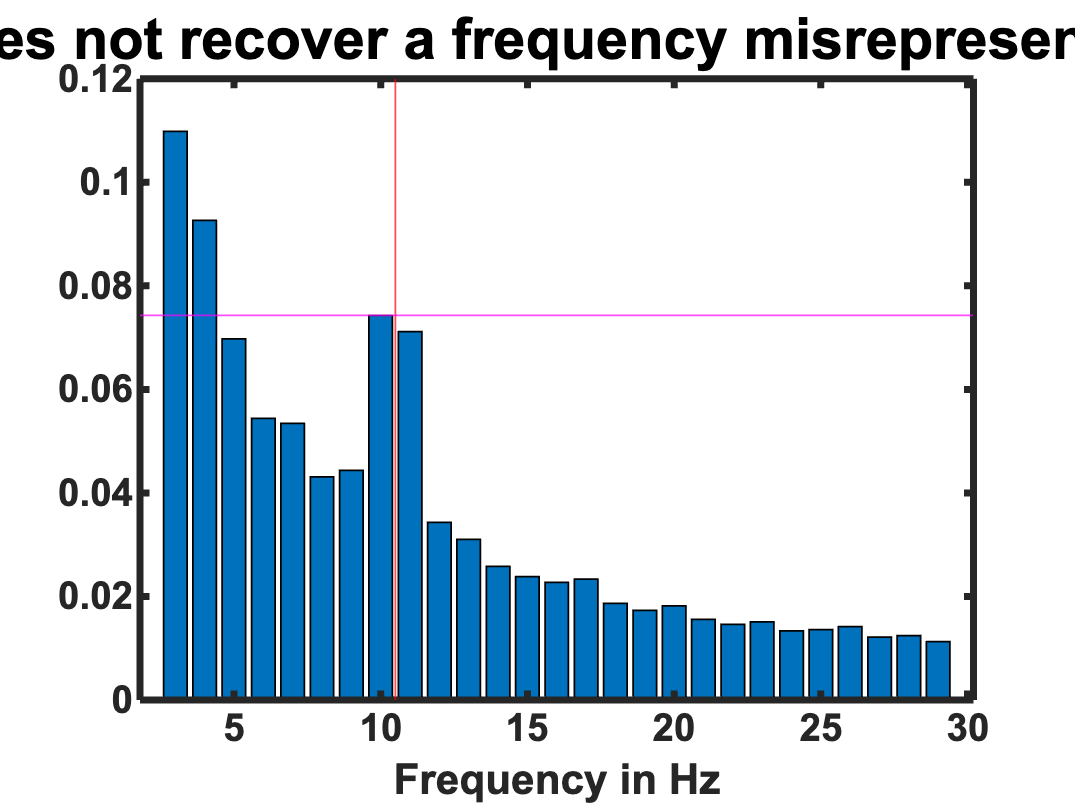

figure
amplitudespec50 = []; 
SinWave = sin(2*pi*time*10.5); % a 10.5 Hz sine wave
for trial = 1:50
    temp1 = rand(size(time))-.5; % zero-centered white nois
    brownsig = cumsum(temp1);  % Brownian noise is the cumulative sum of white noise    
    testsig2  = brownsig-mean(brownsig); % zero-centered Brownian noise
    testsig1 = testsig2 + SinWave; % add the sine wave
    testsig = detrend(testsig1); % detrend
    complexspectrum = fft((testsig(1:1000)));
    amplitudespec50(trial,:) = abs(complexspectrum./length(segment));
end
faxis = 0:500;
bar(faxis(4:30), mean(amplitudespec50(:, 4:30))); 
title(['Averaging does not recover a frequency misrepresented by the DFT']) % the absolute value (amplitude)
xlabel('Frequency in Hz') 
xline(10.5, 'r')
yline (mean(amplitudespec50(:, 11)), 'm')

It is apparent that averaging many trials with the 10.5 Hz signal misrepresented recovered some of the signal but it still fails to indicate its exact frequency. When aiming to measure a narrow band signal of interest, it is recommended to ensure that a frequency bin is located in the spectrum exactly at the frequency of interest. This can be ensured by calculating the wavelength (cycle duration) of the frequency of interest and using an integer multiple of that frequency. In our case: 

% the wavelength of 10.5 Hz oscillation
cycleduration = 1000/10.5 % in miliseconds

cycleduration = 95.2381

% display the window length in miliseconds that result in spectra with a
% bin at 10.8 Hz
durationvector = cycleduration:cycleduration:6000;
disp(durationvector')

   1.0e+03 *

    0.0952
    0.1905
    0.2857
    0.3810
    0.4762
    0.5714
    0.6667
    0.7619
    0.8571
    0.9524
    1.0476
    1.1429
    1.2381
    1.3333
    1.4286
    1.5238
    1.6190
    1.7143
    1.8095
    1.9048
    2.0000
    2.0952
    2.1905
    2.2857
    2.3810
    2.4762
    2.5714
    2.6667
    2.7619
    2.8571
    2.9524
    3.0476
    3.1429
    3.2381
    3.3333
    3.4286
    3.5238
    3.6190
    3.7143
    3.8095
    3.9048
    4.0000
    4.0952
    4.1905
    4.2857
    4.3810
    4.4762
    4.5714
    4.6667
    4.7619
    4.8571
    4.9524
    5.0476
    5.1429
    5.2381
    5.3333
    5.4286
    5.5238
    5.6190
    5.7143
    5.8095
    5.9048
    6.0000



A 2-sec segment duration would capture the 10.5 Hz oscillation. Let's try out what difference this makes

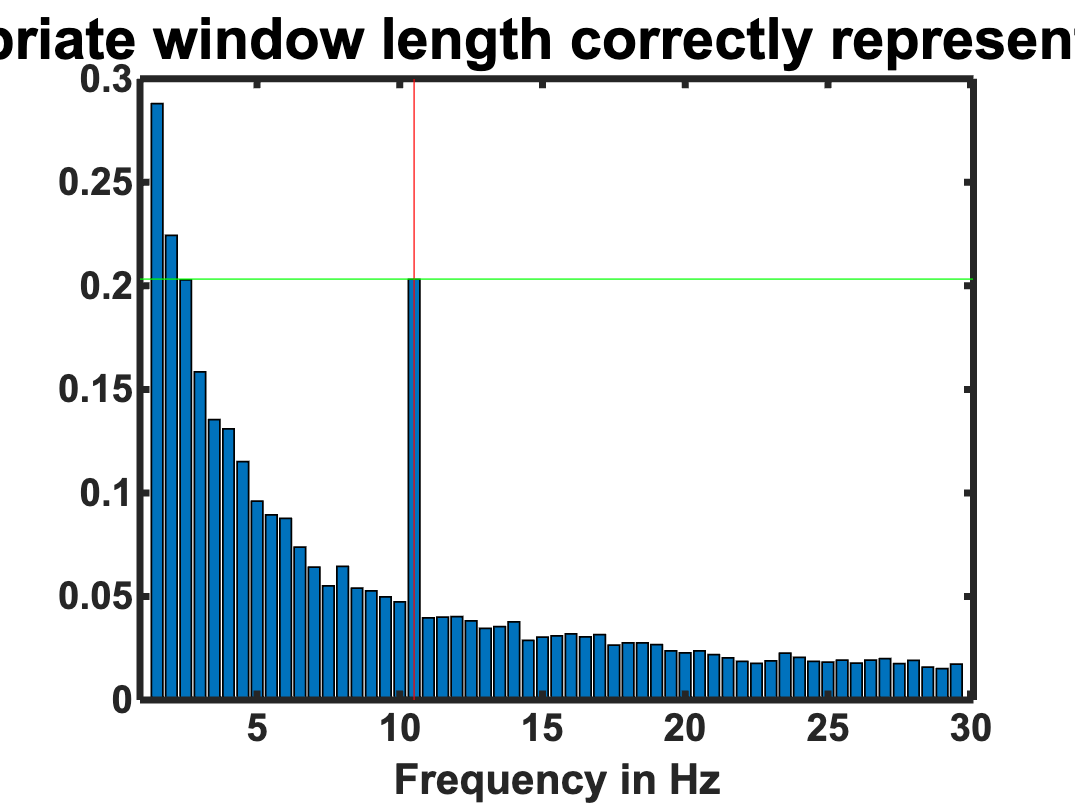

figure
amplitudespec50 = []; 
SinWave = sin(2*pi*time*10.5); % a 10.5 Hz sine wave
for trial = 1:50
    temp1 = rand(size(time))-.5; % zero-centered white nois
    brownsig = cumsum(temp1);  % Brownian noise is the cumulative sum of white noise    
    testsig2  = brownsig-mean(brownsig); % zero-centered Brownian noise
    testsig1 = testsig2 + SinWave; % add the sine wave
    testsig = detrend(testsig1); % detrend
    complexspectrum = fft((testsig(1:2000)));
    amplitudespec50(trial,:) = abs(complexspectrum./length(segment));
end
faxis = 0:0.5:500;
bar(faxis(4:60), mean(amplitudespec50(:, 4:60))); 
title(['Selecting the appropriate window length correctly represents narrow band signal']) % the absolute value (amplitude)
xlabel('Frequency in Hz') 
xline(10.5, 'r')
yline (mean(amplitudespec50(:, 22)), 'g')

It is evident that the 10.5 Hz oscillation is not just more concentrated in one bin, but that the total amplitude captured with appropriate frequency resolution (horizontal green line) exceeds the amplitude estimated from the combined 10 and 11 Hz bins in the 1-sec spectrum (horizontal magenta line in the figure above). Thus, leaking leads to underestimation of the true spectral amplitude and will bias empirical studies of narrow band oscillations. How about broader-band phenomena? We will examine this question next. 

### Part 2: Representing broad-band phenomona in the DFT amplitude spectrum and the inverse problem 

In this second portion of the demo, we will examine the ability of DFT to characterize rhythmic activity that is more variable in frequency, covering a broader band, i.e. multiple frequencies, rather than one frequency. 

We start by making a discrete time vector, at which the signal will be sampled. 

clear
time = 0.001:0.001:1; % one second of discrete time
faxis = 0:500; % frequency axis goes from 0 to nyquist in steps of 1

... now we make 50 trials of white noise (stochastic) segments, the same noise to be used for all future simulations in this demo. We display the noise and the spectrum of each simulated trial. Note the flat nature of the spectrum

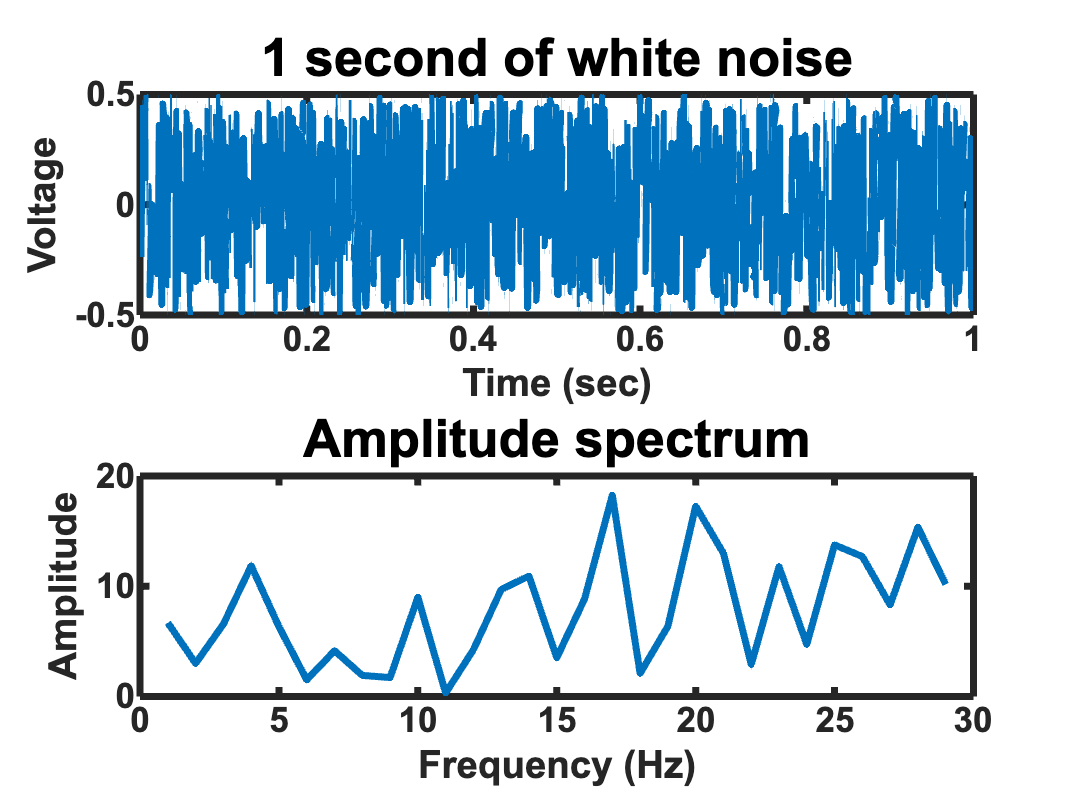

whitesig = rand(50,1000)-.5; % zero centered white noise

for trial = 1:50
    subplot(2,1,1), plot(time, whitesig(trial, :)), xlabel('Time (sec)'), ylabel('Voltage'), title('1 second of white noise')
    fftspec = fft(whitesig(trial, :)'); % calculate DFT
    sumspec(trial, :) = abs(fftspec); % save it for later
    subplot(2,1,2), plot(abs(fftspec (2:30))), xlabel('Frequency (Hz)'),ylabel('Amplitude'),title('Amplitude spectrum')
    pause(.2)

end

Next, we repeat that process with the cumulative sum of the white noise, which results in brownian noise. The spectrum of brownian noise is expected to have a 1/f shape, characteristic for biological (including neural) systems. We also add a brief 400-ms oscillatory response to each trial, in the middle of the 1-sec time segment (300 to 700 ms). Many authors define an oscillation as a narrow band signal, so we add a narrow band signal to each trial, but the exact frequency of the narrow band signal varies between trials. We let it vary to randomly take on values within the young adult alpha range 8 to 13 Hz. 

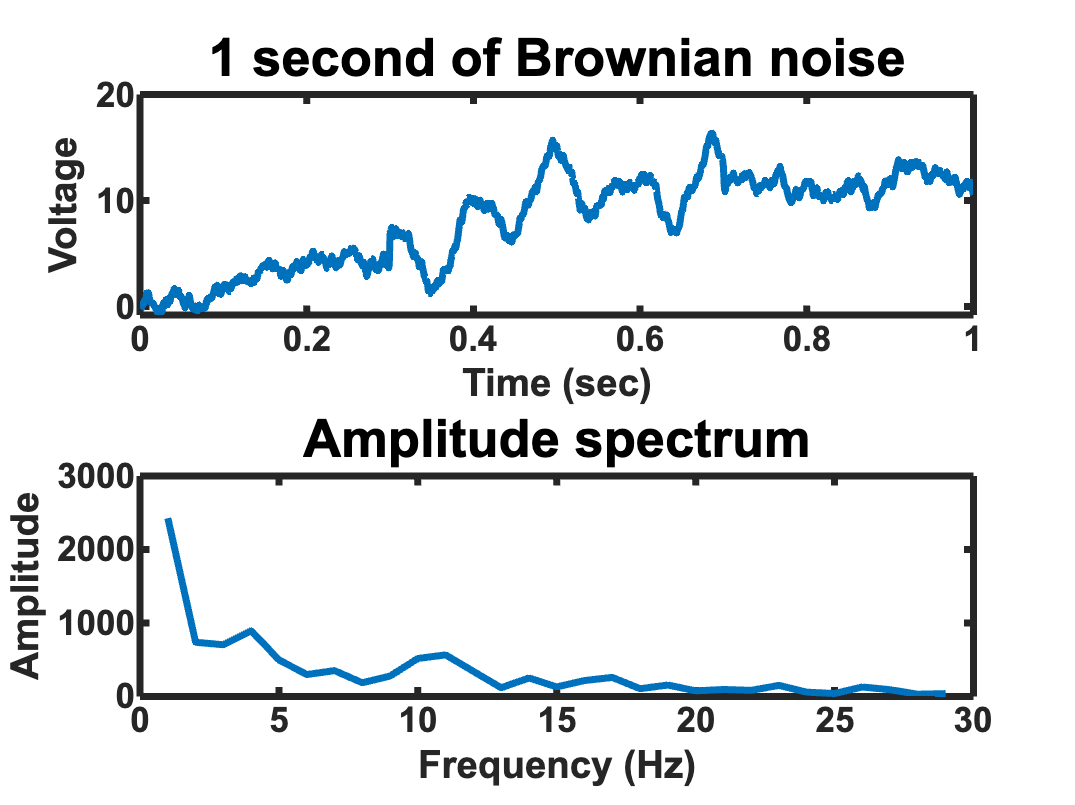

for trial = 1:50
    brownsig(trial,:) = cumsum(whitesig(trial, :));
    alphasig = sin(2*pi*time*(8+rand(1,1).*5)).*3; % * 3 is a scaling factor
    brownsig(trial, 300:700) = brownsig(trial, 300:700) + alphasig(300:700); 
    subplot(2,1,1), plot(time, brownsig(trial,:)), xlabel('Time (sec)'), ylabel('Voltage'), title('1 second of Brownian noise')
    fftspec = fft(brownsig(trial,:)); % calculate DFT
    sumspec1(trial, :) = abs(fftspec); % save it for later
    subplot(2,1,2), plot(abs(fftspec (2:30))), xlabel('Frequency (Hz)'),ylabel('Amplitude'),title('Amplitude spectrum')
    pause(.2)
end

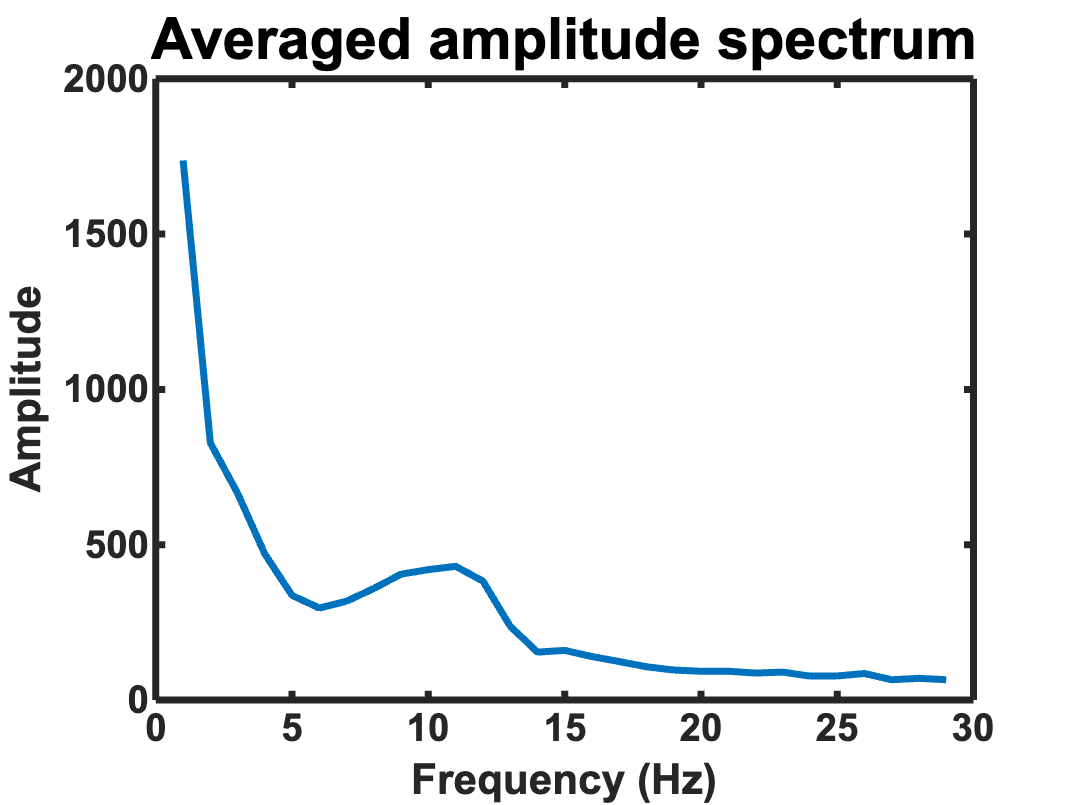


figure
plot(mean((sumspec1(:, 2:30))))
xlabel('Frequency (Hz)'),ylabel('Amplitude'),title('Averaged amplitude spectrum')

Is this result uniquely interpretable as evidence of variable alpha-band events in the 8 to 13 Hz range? Next, we repeat the process above, but we decrease the variability of the temporal rate of the simulated alpha band oscillations to frequencies between 10 and 11 Hz. We also shorten the duration of the oscillatory event to just 200 ms (as opposed to the 400 ms in the example in the previous field). 

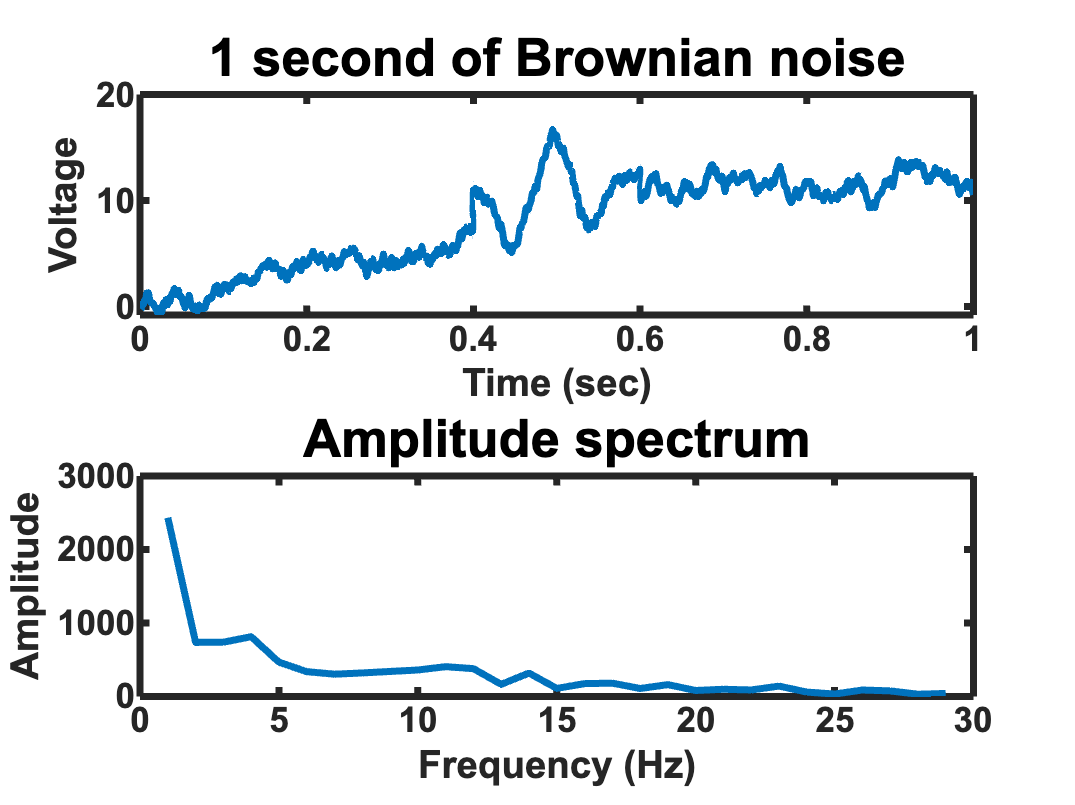

figure
for trial = 1:50
    brownsig(trial,:) = cumsum(whitesig(trial, :));
    alphasig = sin(2*pi*time*(10+rand(1,1).*1)).*4; % * 4 is a scaling factor
    brownsig(trial, 400:600) = brownsig(trial, 400:600) + alphasig(400:600); 
    subplot(2,1,1), plot(time, brownsig(trial,:)), xlabel('Time (sec)'), ylabel('Voltage'), title('1 second of Brownian noise')
    fftspec = fft(brownsig(trial,:)); % calculate DFT
    sumspec2(trial, :) = abs(fftspec); % save it for later
    subplot(2,1,2), plot(abs(fftspec (2:30))), xlabel('Frequency (Hz)'),ylabel('Amplitude'),title('Amplitude spectrum')
    pause(.2)
end

Let's compare the results. In red, the averaged spectrum (the average of 50 spectra for 50 trials) with oscillatory events in the range from 300 to 700 ms of the 1000 ms (1-second) segment, varying between 8 and 13 Hz across trials. In blue, the averaged spectrum (the average of 50 spectra for 50 trials) with oscillatory events in the range from 400 to 600 ms of the 1000 ms (1-second) segment, varying between 10 and 11 Hz across trials.

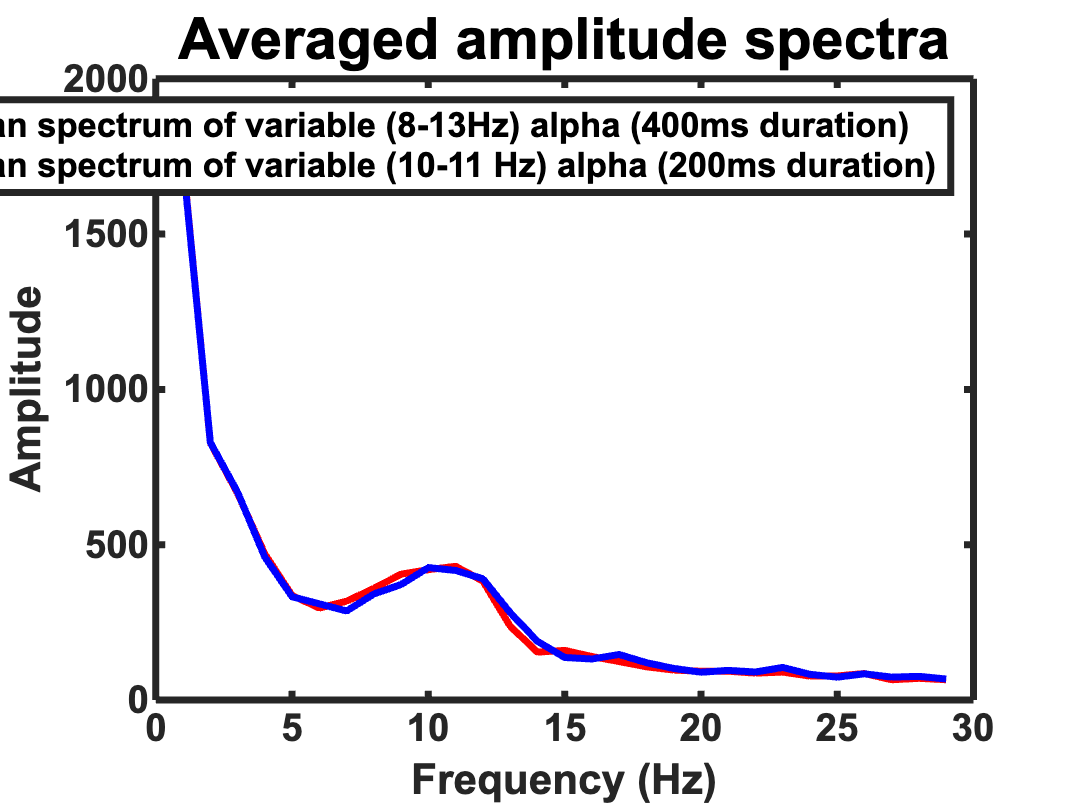

figure
plot(mean((sumspec1(:, 2:30))), 'r')
hold on
plot(mean((sumspec2(:, 2:30))), 'b')
xlabel('Frequency (Hz)'),ylabel('Amplitude'),title('Averaged amplitude spectra')
legend('Mean spectrum of variable (8-13Hz) alpha (400ms duration)', 'Mean spectrum of variable (10-11 Hz) alpha (200ms duration)')

The results show that in most runs (feel free to run this simulation multiple times), the two spectra cannot be reliably discriminated. A shorter burst of a narrow band oscillation may look like longer bursts of a more variable oscillation, because the shorter burst cannot be localized as well in the frequency domain, and spread out across the x-axis (frequency axis) of the spectrum. Non-oscillatory (transient) events may also be misrepresented in that way. Feel free to change the code in line 108 to make shorter bursts than 400:600 ms, to see the effects of a shorter amplitude modulation in the data. Thus, based on the shape of the averaged power spectrum alone, it is difficult to infer the causes that led to what appears to be an alpha peak in the spectrum. This lack of unique interpretability is known as the *inverse problem* and is ubiquitous in scientific measurement theory: Inferring the causes of a low-dimensional measurement is often compared to the task of guessing what 3-D object cast a 2-dimensional shadow on the wall . There are infinite numbers of objects that are capable of casting the same 2-D shadow, and thus a unique inference cannot be made without further information or assumptions (here is a discussion of the inverse problem in source estimation: [http://www.scholarpedia.org/article/Source_localization#An_overview_of_all_the_models](http://www.scholarpedia.org/article/Source_localization#An_overview_of_all_the_models)). The same is the case with averaged spectra. Examining the temporal dynamics of the oscillation, as well as single-trial amplitude/power spectra, and the phase spectrum are viable strategies for addressing this problem.  